# **Lab4 - Tipuri de defecte**

Sa luam ecuatia nominala

$\left\lbrace \begin{array}{l}
\dot{x} \left(t\right)=A_n x\left(t\right)+B_n u\left(t\right)\\
y\left(t\right)=C_n x\left(t\right)
\end{array}\right.$. Sistemul este strict propriu aici si noi evaluam dupa dinamica sistemului

De aici definim $\left\lbrace \begin{array}{l}
\textrm{Defecte}\;\textrm{modelate}\;\textrm{aditiv}\left\lbrace \begin{array}{l}
\dot{x} =A_n x+B_n u+E_d d+E_f f\\
y=C_n x+0u+G_d d+G_f f
\end{array}\right.\\
\textrm{Defecte}\;\textrm{modelate}\;\textrm{multiplicativ}\left\lbrace \begin{array}{l}
\dot{x} =A_f x+B_f u+E_d d\\
y=C_f x+0u+G_d d
\end{array}\right.
\end{array}\right.$, unde $\left\lbrace \begin{array}{l}
x=\textrm{vectorul}\;\textrm{starilor}\\
u=\textrm{vectorul}\;\textrm{intrarilor}\\
y=\textrm{vectorul}\;\textrm{iesirilor}\\
d=\textrm{vectorul}\;\textrm{perturbatiilor}\\
f=\textrm{vectorul}\;\textrm{defectelor}\;/\;\textrm{avarilor}
\end{array}\right.$. La CO vom analiza si utiliza sisteme in care defectele sunt modelate multiplicativ (este ceva mai generic)

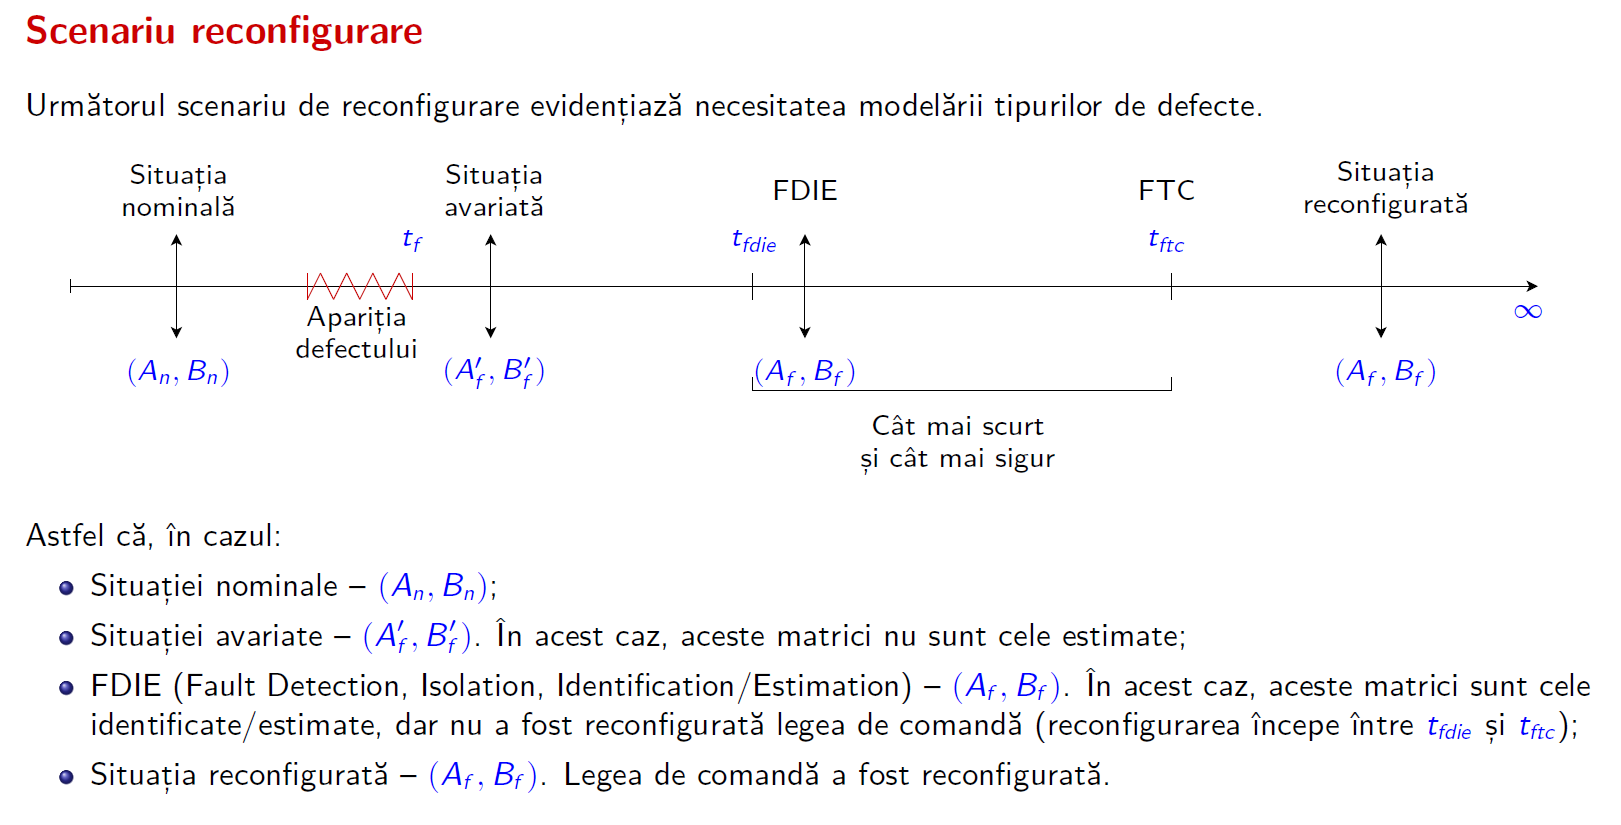

**Ce efect poate avea asta? **Se corupe sau cel mai rau caz se intrerupe legatura dintre sistem si compensator. Asta inseamna ca procesul nostru poate deveni **ori partial ori complet neobservabil**

**In mod ideal, functuinlarea nominala a senzorilor este **$y_{f_i } \left(t\right)=x_i \left(t\right),\forall t\ge 0,\textrm{adica}\;C_f =I_n$

## Orice senzor poate avea defecte. Sa vedem tipurile de defecte:

### Prag

Acest defect introduce o **eroare constanta** in semnalul masurat, **translatand** valoarea acestuia cu un *offset *determinat de coeficientul $f_i$


$$\left\lbrace \begin{array}{l}
y_{f_i } =x_i +f_i \\
\dot{f_i } \equiv 0,f_i \left(t\right)\not= 0,\forall t\ge t_{f_i } 
\end{array}\right.,\textrm{unde}\;\left\lbrace \begin{array}{l}
t_{f_i } \;\textrm{momentul}\;\textrm{cand}\;\textrm{apare}\;\textrm{avaria}\;i\\
f_i \;\textrm{coeficient}\;\textrm{de}\;\textrm{acuratete}\;0<v_{\min } \le f_i \le v_{\max } 
\end{array}\right.$$


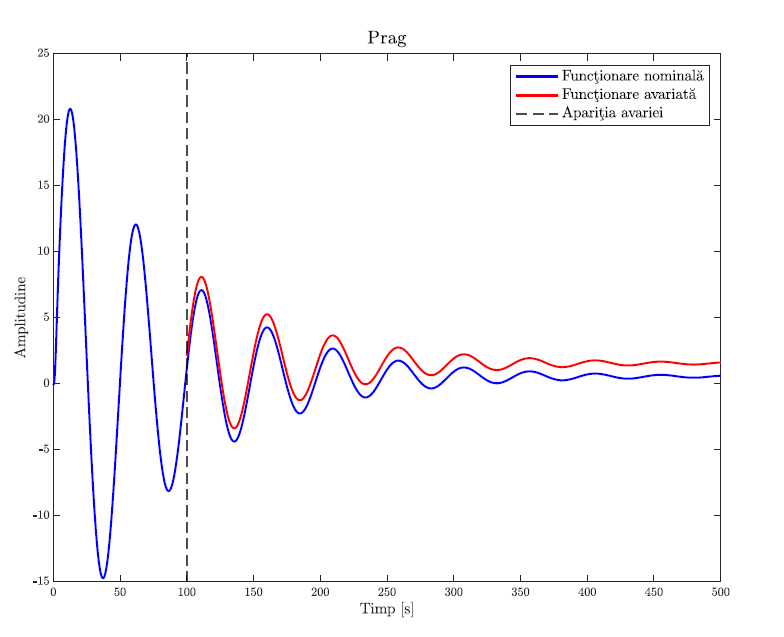

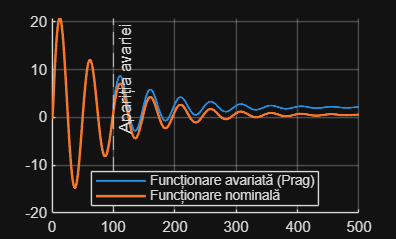

clear
close all
clc

load("E:\Radu editing document\SS + TCAI + TSA\CO + RSA\CO+RSA\CO+RSA\CO\Lab_Daniel\RCAM.mat");

t = linspace(0, 500, 1000);
t_defect = 100;

u1 = 0.05 * double(t >= 0);
u2 = 0.02 * double(t >= 0);
u = [u1; u2];

y = lsim(ss_lon, u, t);

prag = 1.57; 

fault_mask = double(t >= t_defect);

y_prag = y + (prag * [fault_mask; fault_mask; fault_mask])';

figure
hold on

plot(t, y_prag(:,2), 'LineWidth', 1.2, 'DisplayName', 'Funcționare avariată (Prag)')
plot(t, y(:,2), 'LineWidth', 1.5, 'DisplayName', 'Funcționare nominală')

xline(t_defect, '--', 'Apariția avariei', 'HandleVisibility', 'off');

grid on
legend('Location', 'best');

### Deviere

Produce o eroare care **creste sau scade progresiv in timp**, determinand o **abatere liniara** a semnalului masurat fata e valoarea reala

$\left\lbrace \begin{array}{l}
y_{f_i } =x_i +f_i \\
|f_i \left(t\right)|=I_i t,0<I_i <<1,\forall t\ge t_{f_i } 
\end{array},\textrm{unde}\;t_{f_i } \right.$momentul la care apare avaria

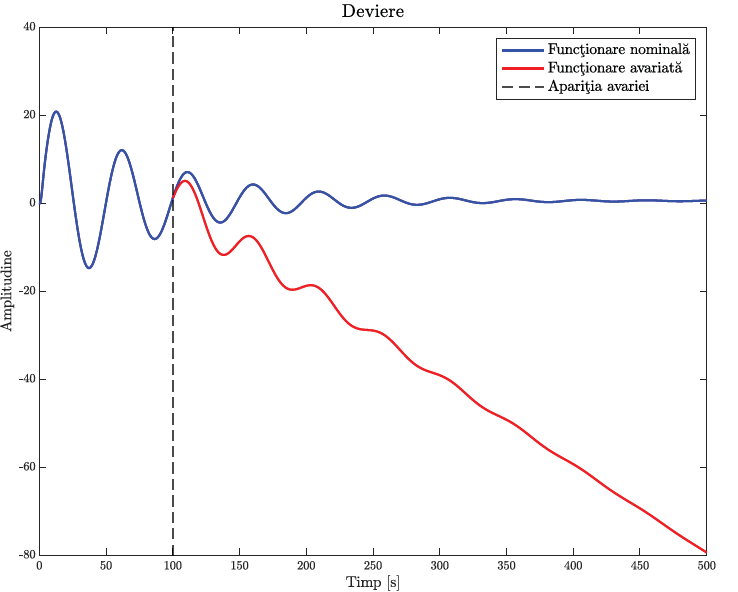

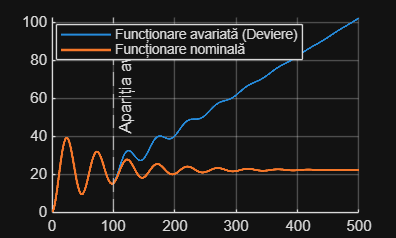

clear
close all
clc

load("E:\Radu editing document\SS + TCAI + TSA\CO + RSA\CO+RSA\CO+RSA\CO\Lab_Daniel\RCAM.mat");

t = linspace(0, 500, 1e4);
t_defect = 100;

u1 = 0.05 * double(t>=0);
u2 = 0.02 * double(t>=0);
u = [u1; u2];

y = lsim(ss_lon, u, t);

deviere_rate = 0.2;


drift_signal = double(t >= t_defect) .* (t - t_defect) * deviere_rate;


y_deviere = y + [drift_signal; drift_signal; drift_signal]';

%% Visualization
figure
hold on

plot(t, y_deviere(:,3), 'LineWidth', 1.2, 'DisplayName', 'Funcționare avariată (Deviere)');
plot(t, y(:,3), 'LineWidth', 1.5, 'DisplayName', 'Funcționare nominală');

% Sync xline with t_defect
xline(t_defect, '--', 'Apariția avariei', 'HandleVisibility', 'off');

grid on
legend('Location', 'best');

### Pierderea acuratetei (degradarea senzorului)

Determina aparitia unor** fluctuatii aleatoare** in semnalul masurat, reprezentand **degradarea preciziei** senzorului


$$\begin{array}{l}
y_{f_i } =x_i +f_i \\
|f_i \left(t\right)|=\bar{f_i } ,\dot{f_i \left(t\right)\to 0,} \forall t\ge t_{f_i } 
\end{array}$$

$$\textrm{unde}\;\left\lbrace \begin{array}{l}
t_{f_i } \;\textrm{momentul}\;\textrm{cand}\;\textrm{apare}\;\textrm{avaria}\;i\\
f_i \;\textrm{coeficient}\;\textrm{de}\;\textrm{acuratete}\;0<v_{\min } \le f_i \le v_{\max } 
\end{array}\right.$$


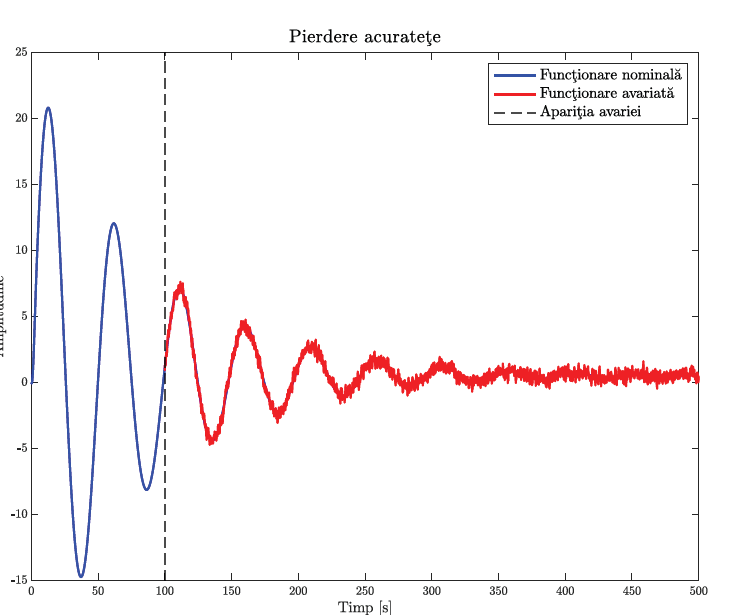

clear
close all
clc

load("E:\Radu editing document\SS + TCAI + TSA\CO + RSA\CO+RSA\CO+RSA\CO\Lab_Daniel\RCAM.mat");

t = linspace(0, 500, 1e4);
t_defect = 100;
idx = find(t >= t_defect, 1);

u1 = 0.05 * double(t>=0);
u2 = 0.02 * double(t>=0);
u = [u1; u2]

u =     0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500
    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0

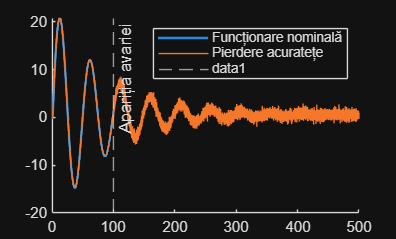


% Nominal Simulation
y = lsim(ss_lon, u, t);
y_nom = y(:, 2); 

% Add Noise: randn generates normal distribution noise
noise_amplitude = 0.6; 
y_fault = y_nom;
y_fault(idx:end) = y_fault(idx:end) + noise_amplitude * randn(size(t(idx:end)))';

figure; hold on;
plot(t, y_nom, 'LineWidth', 1.5, 'DisplayName', 'Funcționare nominală');
plot(t, y_fault, 'DisplayName', 'Pierdere acuratețe');
xline(t_defect, '--', 'Apariția avariei');
legend;

### Inghetare

Apar cand senzorul **inceteaza sa mai actualizeze valoarea masurata** si ramane** blocat la ultima valoare** inregistrata

$y_{f_i } =x_i +f_i$, unde $t_{f_i } \;\textrm{momentul}\;\textrm{cand}\;\textrm{apare}\;\textrm{avaria}\;i$

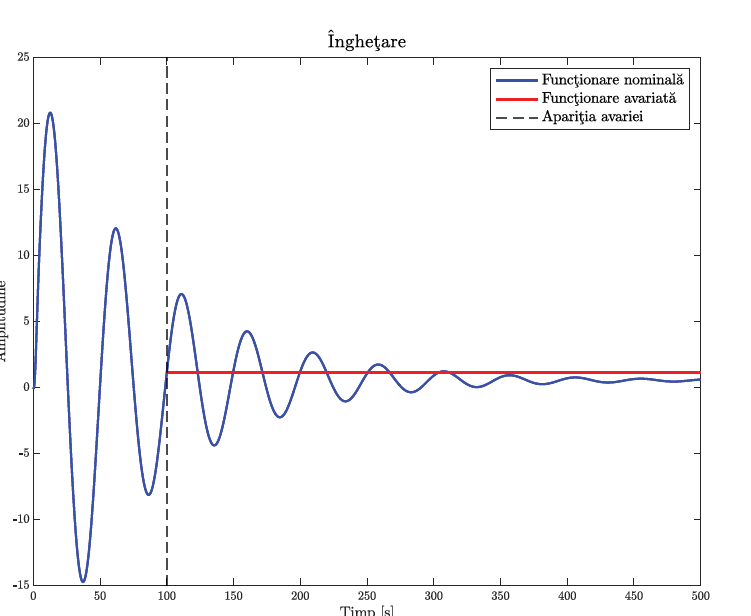

clear
close all
clc

load("E:\Radu editing document\SS + TCAI + TSA\CO + RSA\CO+RSA\CO+RSA\CO\Lab_Daniel\RCAM.mat");

t = linspace(0, 500, 1000);
t_defect = 100;
idx = find(t >= t_defect, 1);

u1 = 0.05 * double(t>=0);
u2 = 0.02 * double(t>=0);
u = [u1; u2]

u =     0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500
    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0

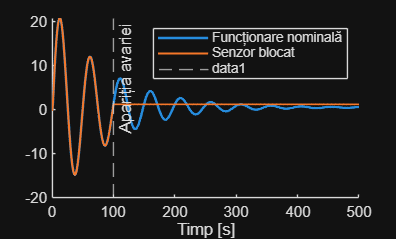


y = lsim(ss_lon, u, t);
y_nom = y(:, 2);

% Freeze the signal at the value it had at t_defect
y_stuck = y_nom;
y_stuck(idx:end) = y_nom(idx); 

figure; hold on;
plot(t, y_nom, 'LineWidth', 1.5, 'DisplayName', 'Funcționare nominală');
plot(t, y_stuck, 'LineWidth', 1.2, 'DisplayName', 'Senzor blocat');
xline(t_defect, '--', 'Apariția avariei');
legend; xlabel('Timp [s]');

### Pierderea eficientei (afectarea calibratii)

Determina o modificare a amplificarii senzorului, astfel incat **valoarea masurata devine proportionala cu semnalul real printr-un facor de scalare mai mic decat unitatea**. In consecinta, **amplificarea semnalului **este **redusa**, reducere **data de **$c_f$.

$y_{f_i } =c_{f_i } {\;*\;x}_i ,\forall t\ge t_{f_i }$, unde $\left\lbrace \begin{array}{l}
t_{f_i } \;\textrm{momentul}\;\textrm{la}\;\textrm{care}\;\textrm{apare}\;\textrm{avaria}\;i\\
c_{f_i } \in \left(0,1\right)\;\textrm{coeficientul}\;\textrm{de}\;\textrm{eficienta}\to \textrm{se}\;\textrm{reflecta}\;\textrm{in}\;\textrm{elementele}\;\textrm{lui}\;C_f 
\end{array}\right.$

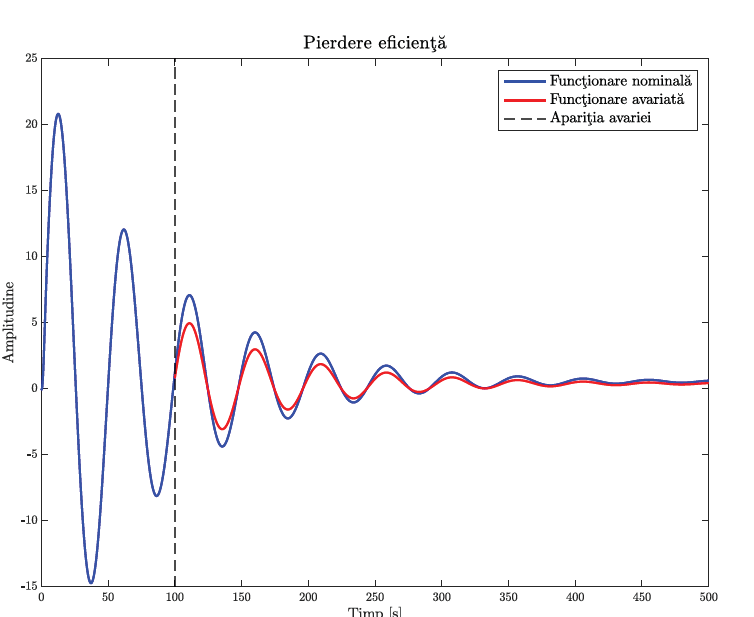

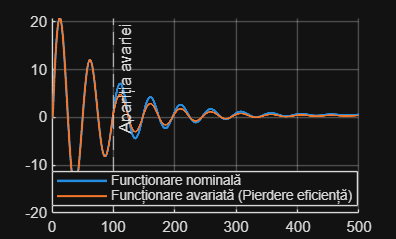

clear
close all
clc

load("E:\Radu editing document\SS + TCAI + TSA\CO + RSA\CO+RSA\CO+RSA\CO\Lab_Daniel\RCAM.mat");

t = linspace(0, 500, 1e4);
t_defect = 100;

u1 = 0.05 * double(t >= 0);
u2 = 0.02 * double(t >= 0);
u = [u1; u2];

y = lsim(ss_lon, u, t);

coef_eficienta = 0.68; 

gain_vector = ones(size(t));
gain_vector(t >= t_defect) = coef_eficienta;

y_eficienta = y .* gain_vector';

figure
hold on
plot(t, y(:,2), 'LineWidth', 1.5, 'DisplayName', 'Funcționare nominală');
plot(t, y_eficienta(:,2), 'LineWidth', 1.2, 'DisplayName', 'Funcționare avariată (Pierdere eficiență)');

xline(t_defect, '--', 'Apariția avariei', 'HandleVisibility', 'off');

grid on
legend('Location', 'best');

Acum am vorbit de defecte la senzori prin care am vazut ca putem pierde o parte sau chiar toata obervabilitatea. Exista ceva prin care putem pierse o parte sau toata **controlabilitatea? **Din pacate da, si anume *Defecte de efectori*

**Comportament nominal**$\Rightarrow$legea de comanda post-avarie este identica celei din cazul nominal: $u_{f_i } \left(t\right)=u_{n_i } ,\forall t\ge 0$

## Si aici, din pacate, avem mai multe tipuri de defecte de efectori

### Blocare

Apare atunci cand **efectorul ramane blocat la o anumita valoare a comenzii**, fara a mai putea urmari **variatiile ulterioare** ale semnaului de comanda

$u_{f_i } \left(t\right)=u_{n_i } \left(t_{f_i } \right),\forall t\ge t_{f_i }$, unde $\left\lbrace \begin{array}{l}
t_{f_i } \;\textrm{momentul}\;\textrm{de}\;\textrm{timp}\;\textrm{al}\;\textrm{defectului}\;\textrm{pentru}\;\textrm{efectorul}\;i\\
u_n \;\textrm{comanda}\;\textrm{nominala}\;\textrm{calculata}\;\textrm{de}\;\textrm{regulator}
\end{array}\right.$

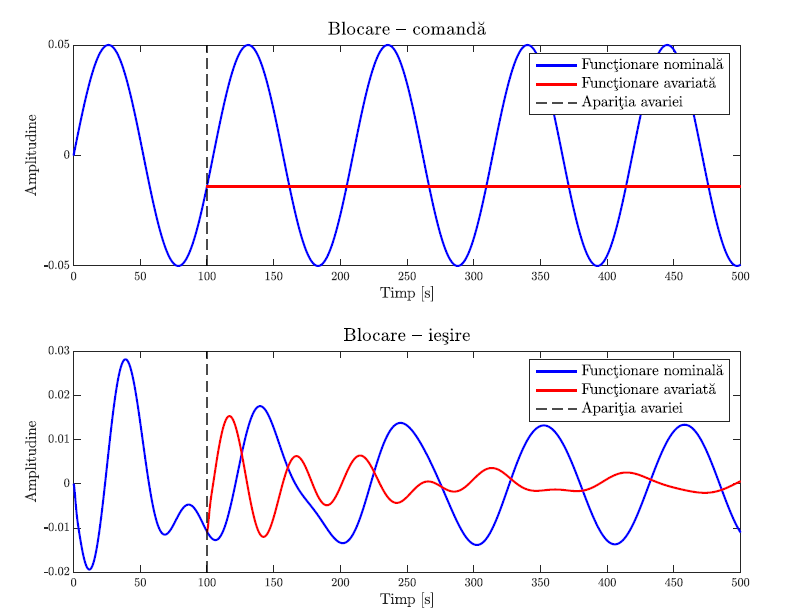

### Saturatie

**Limiteaza** amplitudinea semnalului se comanda la un interval finit $\left\lbrack u_{\min } ,u_{\max } \right\rbrack$. Daca acest** inteval este depasit**, efectorul **nu mai poate reproduce fidel** semnalul de comanda, iar valoarea aplicata sistemului este **saturata la limita corespunzatoare**


$$\left\lbrace \begin{array}{l}
u_{f_i } \left(t\right)=u_{n_i }^{\min } \\
u_{f_i } \left(t\right)=u_{n_i }^{\max } 
\end{array}\right.,\forall t\ge t_{f_i }$$

$$\left\lbrace \begin{array}{l}
t_{f_i } \;\textrm{momentul}\;\textrm{de}\;\textrm{timp}\;\textrm{al}\;\textrm{defectului}\;\textrm{pentru}\;\textrm{efectorul}\;i\\
u_n \;\textrm{comanda}\;\textrm{nominala}\;\textrm{calculata}\;\textrm{de}\;\textrm{regulator}
\end{array}\right.$$


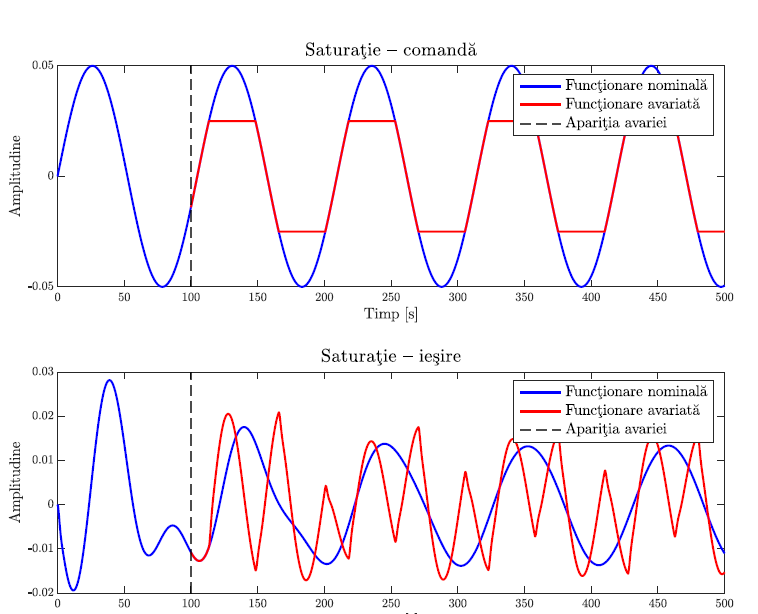

### Flotare (cam moare efectorul)

Apare atunci cand efectorul isi** pierde capacitatea** de a** aplica comanda** asupra sistemului, iar **semnalul de control devine nul**


$$u_{f_i } \left(t\right)=0,\forall t\ge t_{f_i }$$

$$\left\lbrace \begin{array}{l}
t_{f_i } \;\textrm{momentul}\;\textrm{de}\;\textrm{timp}\;\textrm{al}\;\textrm{defectului}\;\textrm{pentru}\;\textrm{efectorul}\;i\\
u_n \;\textrm{comanda}\;\textrm{nominala}\;\textrm{calculata}\;\textrm{de}\;\textrm{regulator}
\end{array}\right.$$


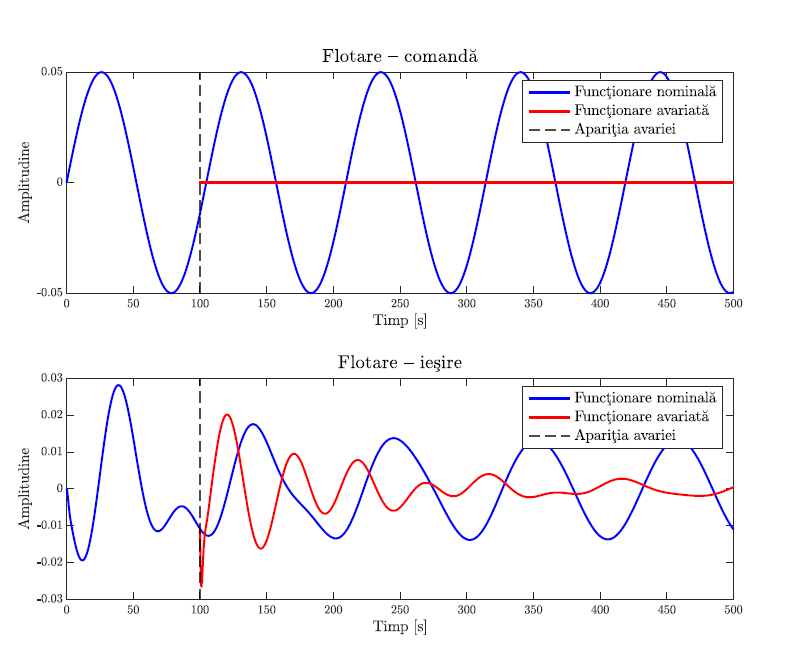

### Pierderea eficientei

Reduce capacitatea de a genera comanda dorita. Semnalul aplicat sistemului devine o fractiune din comanda nominala, fiind calat cu coeficientul de eficienta $\tau_f$

$u_{f_i } \left(t\right)=\left(1-\tau_{f_i } \right)u_{n_i } \left(t\right),\forall t\ge t_{f_i }$, unde $\left\lbrace \begin{array}{l}
t_{f_i } \;\textrm{momentul}\;\textrm{de}\;\textrm{timp}\;\textrm{al}\;\textrm{defectului}\;\textrm{pentru}\;\textrm{efectorul}\;i\\
u_n \;\textrm{comanda}\;\textrm{nominala}\;\textrm{calculata}\;\textrm{de}\;\textrm{regulator}\\
\tau_{f_i } \in \left(0,1\right)\;\textrm{coeficient}\;\textrm{de}\;\textrm{eficienta}\;\textrm{care}\;\textrm{se}\;\textrm{reflecta}\;\textrm{in}\;B_f ,B_f =\left(1-\tau_f \right)B_n 
\end{array}\right.$

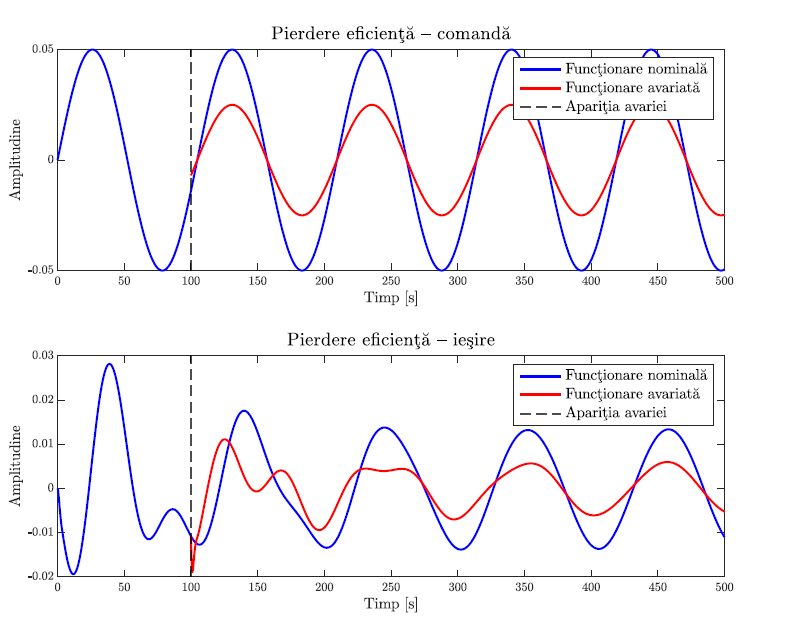

## Ghici ce? 3 nu este numar norocos, mai avem un fel de defect. Mai precis, Defecte de proces

Au ca efect modificari in evolutia dinamica a procesului

- Dificile de modelat

- Se presupune ca procedura de diagnoza este capabila sa propuna o expresie pentru matricea $A_f$

- **Ideea:** se considera ca matricea dinamica a sistemului din evolutia nominala se modifica in $A_f =A_n +\Delta A_f$ sau $A_f =\left(1-\gamma_f \right)A_n$ cu $\gamma_f \in \left(0,1\right)$ cu $\gamma_f <<1$ in functie de cum este modelat defectul

- A,B,C,D aia depind de parametrii, nu sunt fixe

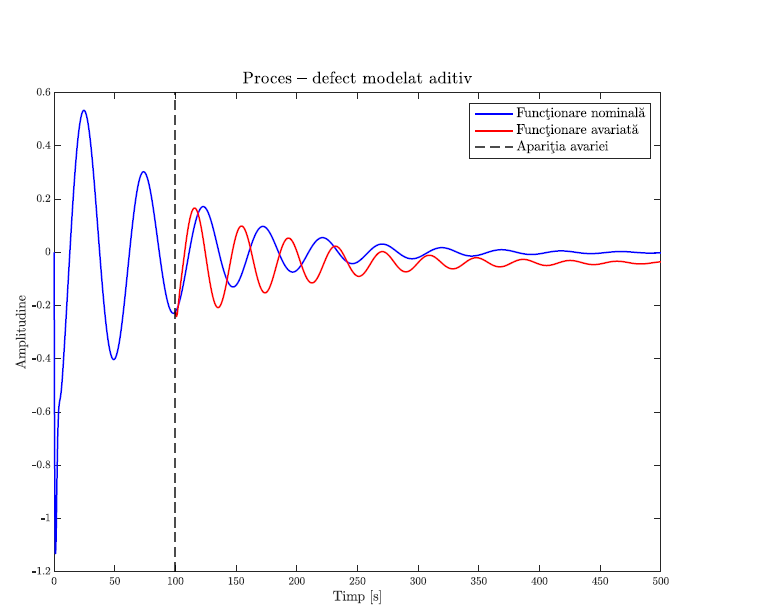

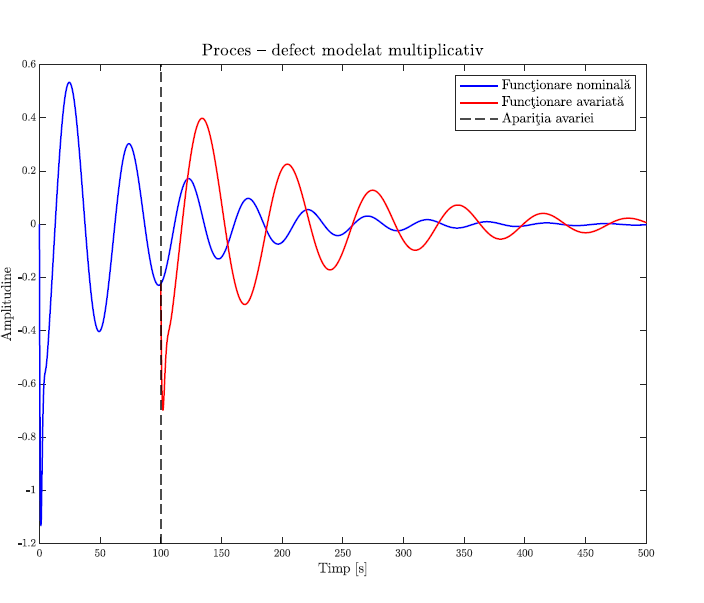

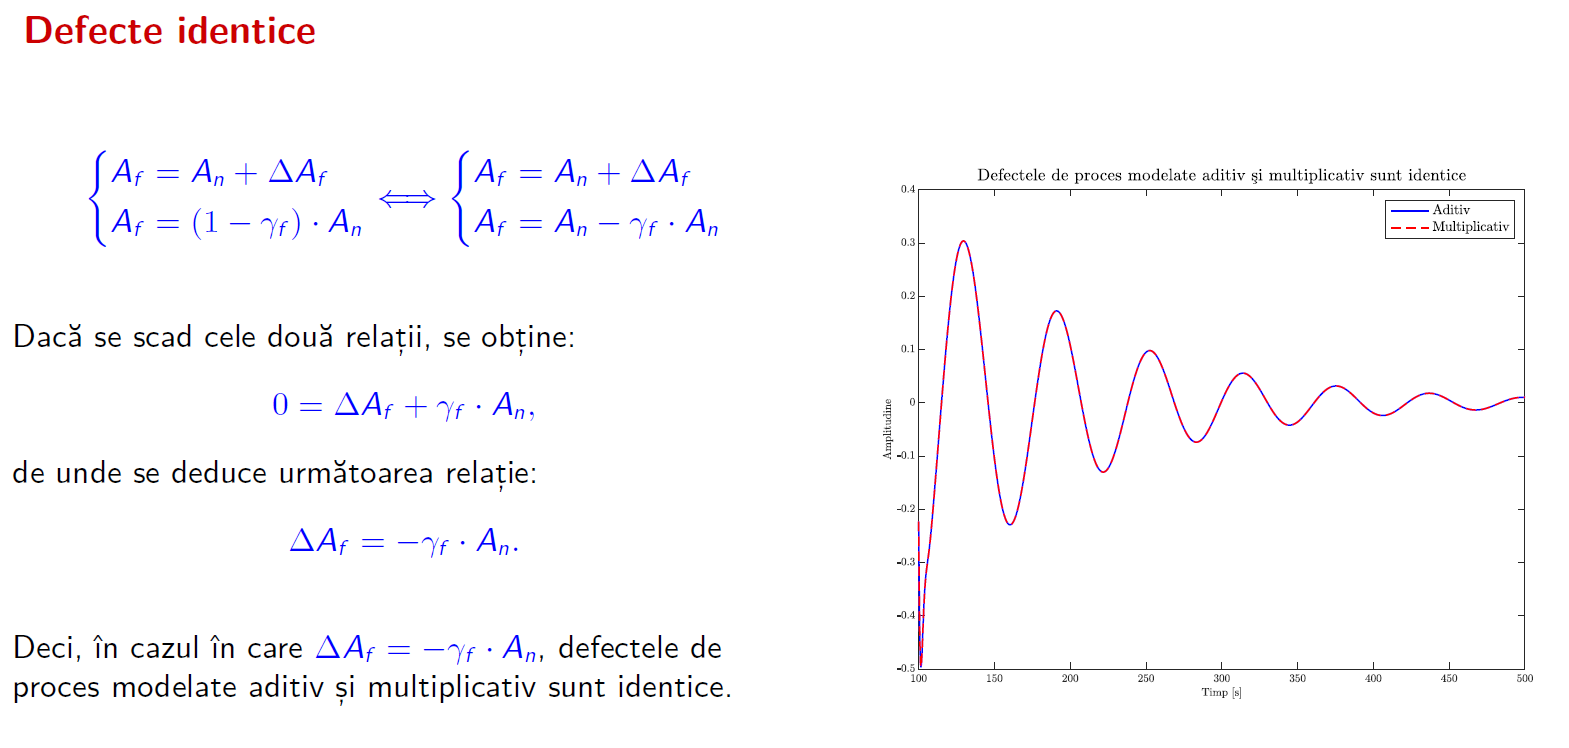

Sa reluam modelele de la Lab1

clear
close all
clc

load("E:\Radu editing document\SS + TCAI + TSA\CO + RSA\CO+RSA\CO+RSA\CO\Lab_Daniel\RCAM.mat");

Pc_lat = ctrb(A_lat, B_lat);
disp('Rangul matricii de ctrb pe lat');
rank(Pc_lat)

Po_lat = obsv(A_lat, C_lat);
disp('Rangul matricii de obsv pe lat');
rank(Po_lat)

Pc_lon = ctrb(A_lon, B_lon);
disp('Rangul matricii de ctrc pe lat');
rank(Pc_lon)

Po_lon = obsv(A_lon, C_lon);
disp('Rangul matricii de obsv pe lat');
rank(Po_lon)

## Aici aplicam toti 3 aia, joaca-te cu parametrii

Bag ceva, hai sa vedem care vrea si care nu

clear
close all
clc

load("E:\Radu editing document\SS + TCAI + TSA\CO + RSA\CO+RSA\CO+RSA\CO\Lab_Daniel\RCAM.mat");

miau = 1;    
    cf = [0.4321 1 0 0  0.241;

Rangul matricii de ctrb pe lat


          0.124132 0 0 0.12 0.12412;

ans = 5

          0.134 0.6431 0.1241 0 0;
          0.434 0.2432 0.65346 0.634 0;
          0.3245 0 0 0 0]; % pierdere eficienta

Rangul matricii de obsv pe lat


    fi = rand; % pragul

ans = 5

    Ii = rand; % Deviere
    Fhati = rand; % pierderea acuratatei
    tauf = rand(5,5); % eficienta

Rangul matricii de ctrc pe lat


    gammaf = rand(5,5);

ans = 4

    
    Cflat = cf * C_lat;
    

Rangul matricii de obsv pe lat


    Aflat = (ones(1,5)-gammaf)*A_lat;

ans = 4

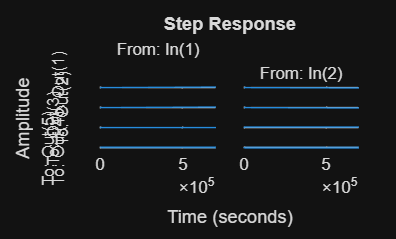

    Bflat = (ones(1,5)-tauf)*B_lat;
    
    Dflat = zeros(5,2);
    
    Flat = ss(Aflat,Bflat,Cflat,Dflat);
    
    Pcf_lat = ctrb(Aflat, Bflat);
    Pof_lat = obsv(Aflat, Cflat);
    if rank(Pcf_lat) < 5 || rank(Pof_lat) < 5
        miau = 0;
        disp('In sfarsit este necontrolabil sau neobservabil')
        
    end

    figure
    step(Flat)
        
    figure
    impulse(Flat)


    disp('Hai si la longitudinal');

    cf = [0.4321 0 0;
          0.124132 0 0 ;
          0.134 0.6431 0;]; % pierdere eficienta
    fi = rand; % pragul
    Ii = rand; % Deviere
    Fhati = rand; % pierderea acuratatei
    tauf = rand(4,4); % eficienta
    gammaf = rand(4,4);

    Cflon = cf * C_lon;
    
    Aflon = (ones(1,4)-gammaf)*A_lon;
    Bflon = (ones(1,4)-tauf)*B_lon;
    
    Dflon = zeros(3,2);
    

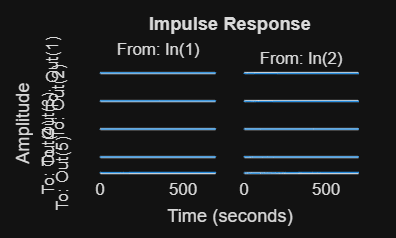

    Flon = ss(Aflon,Bflon,Cflon,Dflon);

    Pcf_lon = ctrb(Aflon, Bflon);

    Pof_lon = obsv(Aflon, Cflon);
    if rank(Pcf_lon) < 4 || rank(Pof_lon) < 4
        miau = 0;

Hai si la longitudinal


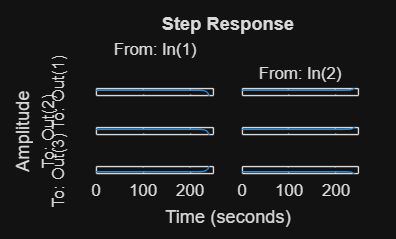

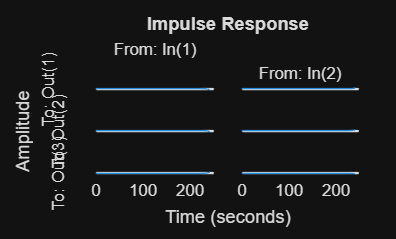

Nu vrea domne


        disp('In sfarsit este necontrolabil sau neobservabil')
        
    end
    figure
    step(Flon)
        
    figure
    impulse(Flon)


if miau == 1
disp('Nu vrea domne')
end

Din pacate, nu am reusit. Bine, nici nu prea ai cum sa faci asta multiplicativ.

Ideea ar fi sa modifici restrictiile astfel incat sa scada rangul matricilor